# Problem 1

## (a) Armijo search function is defined at the bottom of the document

## (b)

f = @(x) (x - pi).^2 - 4;
df = @(x) 2*x - 2*pi;

alpha0 = 250;
tau = 0.7;
beta = 0;

x = 0;
p = 1;
[alpha, its] = armijo(f,df,x,p, alpha0, tau, beta, 1000)

alpha =    4.943316857499997


its =     11


x = 10;
p = -1;
[alpha, its] = armijo(f,df,x,p, alpha0, tau, beta, 1000)

alpha =   10.088401749999994


its =      9


With playing with the parameters, I have found that $\tau$ close to 0 causes Armijo tp converge  very quickly but the range of returned $\alpha$ are narrowed. This makes sense because $\tau$ affects how much we decrease $\alpha$ at each step and so a small $\tau$ causes $\alpha$ to become small very quickly. 

Playing with $\beta$ has shown that $\beta > 1$ cause $\alpha$ to be very small which is not desirable. But, $\beta \in (0,1)$ causes the final $\alpha$ to be more varied. The smaller $\beta$ is, the larger $\alpha$ will be. This trend is due to the stopping criteria being easier to meet.

Finally, the choice of $\alpha_0$ has a small effect on the final $\alpha$ assuming $\alpha_0$ is significantly large. This lack of effect is due to the fact that we are shrinking $\alpha$ until our stopping criteria is met. Thus, if we keep shrinking any large $\alpha$, the possible values for the final $\alpha$ is mainly limited to the stopping criteria parameters such as $\beta$ and the shrinking parameter $\tau$. 

## (c)

format long
epsilon = 10^(-14);

% Armijo parameters
alpha0 = 1000;
tau = 0.5;
beta = 0.25;

% Steepest descent method
x = 0;
its = 1;
while (abs(df(x(its))) > epsilon)
    p = -sign(df(x(its)));
    alpha = armijo(f, df, x(its), p, alpha0, tau, beta);
    
    x(its + 1) = x(its) + alpha*p;
    
    its = its + 1;
    
    if its > 30
        sprintf('Max Iterations Used');
        break;
    end
end

% Dislay number of iterations used
its = its - 1

its =     30


% Check solution
abs(x(end) - pi)

ans =      3.963247507954293e-09


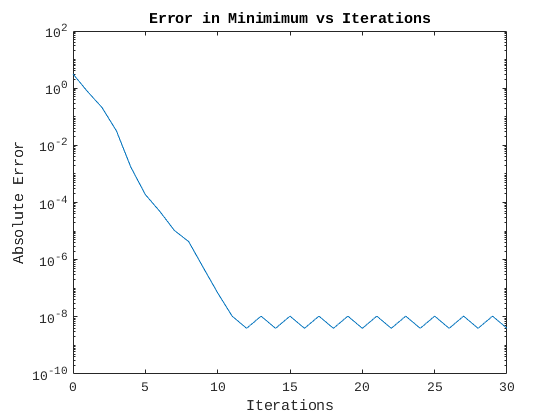

% Plot errors
figure()
semilogy(0:its,abs(x - pi))
xlabel('Iterations')
ylabel('Absolute Error')
title('Error in Minimimum vs Iterations')

From the plot above, we can see that we do converge to solution with an accuracy on the order of $10^{-8}$. Around iteration 11, we don't seem to converge further due to the step size not shrinking. Each iteration after 11 pushes the solution back and forth indefintely because Armijo backtracking no longer decreases the step size. 

# Problem 2

## (a)

To find the minimum of $f(x,y) = x^2 + y^2 + xy$, we need to set the gradient to zero.


$$\nabla f(x,y) = 0 \Longrightarrow \pmatrix{2x + y = 0 \cr 2y + x = 0} \Longrightarrow (x,y) = (0,0)$$


## (b)

f = @(x) x(1).^2 + x(2).^2 + x(1).*x(2);
df = @(x) [2*x(1) + x(2); x(1) + 2*x(2)];

format long
epsilon = 10^(-15);

% Armijo parameters
alpha0 = 1000;
tau = 0.5;
beta = 0.5;

% Steepest descent method
x = [0.25;0.5];
its = 1;
while (norm(df(x(:,its))) > epsilon)
    p = -df(x(:,its));
    alpha = armijo(f, df, x(:,its), p,alpha0, tau, beta);
    
    x(:,its + 1) = x(:,its) + alpha*p;
    
    its = its + 1;
    
    if its > 100
        sprintf('Max Iterations Used');
        break;
    end
end

% Number of iterations used
its = its - 1

its =     46


% Final solution
x(end)

ans =      3.398003253627439e-16


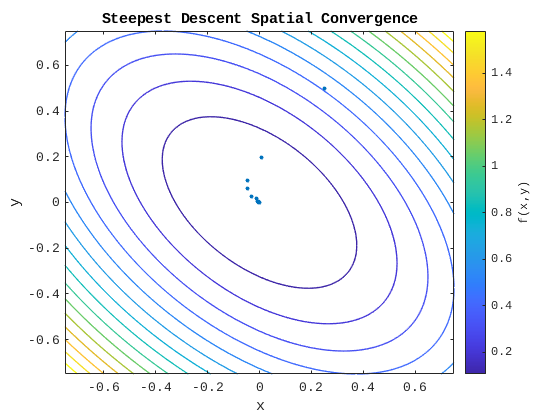

% Contour plot and solution convergence
[X,Y] = meshgrid(linspace(-0.75,0.75,100));
Z = X.^2 + Y.^2 + X .* Y;

figure()
contour(X,Y,Z,15,"LineWidth",1)
c = colorbar();
c.Label.String = 'f(x,y)';
hold on
scatter(x(1,:),x(2,:),10,'filled')
title('Steepest Descent Spatial Convergence')
xlabel('x')
ylabel('y')

Using the steepest descent method, we converged to a minimum in 46 iterations using the parameters above. Changing the initial guess has drastic effects on the number of iterations used. When we choose an intial condition of $x_0 = (0.5,0.5)$, our method converges in 27 iterations. This faster convergence is due to the normals of the contours pointing directly towards the minima. When we use an inital condition of $x_0 = (0.25,0.5)$ as above, convergence is far slower. This slower convergence is due to the normals of the contours not pointing directly at our minima. We can see that the path taken to get to the minima is curvy and inefficient.

Interestingly enough, Armijo backtracking does allow machine precision convergence in this problem. This is most likely due to the 2D nature of the problem. The extra dimensions decreases your chance of hitting stagnation by making it harder for the iterations to bounce between two points indefintiely.

# Problem 3

f = @(x) x(1).^2 + x(2).^2 + x(1).*x(2);
gradf = @(x) [2*x(1) + x(2); x(1) + 2*x(2)];
H = @(x) [2 1; 1 2];

format long
epsilon = 10^(-15);

% Armijo parameter
alpha0 = 1000;
tau = 0.5;
beta = 0.5;

% Newton's optimization method
x = [0.25;0.5];
its = 1;
while (norm(df(x(:,its))) > epsilon)
    p = -H(x(:,its)) \ gradf(x(:,its));
    alpha = armijo(f, gradf, x(:,its), p,alpha0, tau, beta);
    
    x(:,its + 1) = x(:,its) + alpha*p;
    
    if its > 100
        sprintf('Max Iterations Used');
        break;
    end
    
    its = its + 1;
end

% Number of iterations used
its = its - 1

its =     10


% Final solution
x(end)

ans =      2.500822425120643e-17


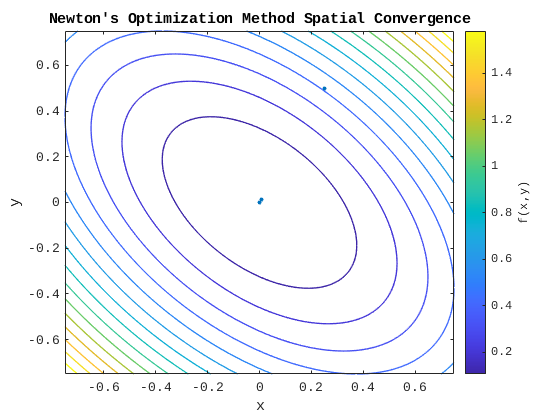

% Contour plot and solution convergence
figure()
contour(X,Y,Z,15,"LineWidth",1)
c = colorbar();
c.Label.String = 'f(x,y)';
hold on
scatter(x(1,:),x(2,:),10,'filled')
title('Newton''s Optimization Method Spatial Convergence')
xlabel('x')
ylabel('y')

In contrast to the steepest descent, Newton's method jumps to the minima very fast. Even though the normals of the contour at the intial guess do not point towards the minima, Newton's method is able to find a better search direction that does point towards the minima. Newton's method has exceptional convergence in this problem because we are minimizing a second degree polynomial (i.e. the Hessian is able to accurately resolve our surface from the local surface information). The fast convergence is still maintained for different starting guesses. 

function [alpha, its] = armijo(f,df,x,p,alpha0,tau,beta,maxIts)
    % Handle default arguments
    switch nargin
        case 4
            alpha0 = 1000;
            tau = 0.5;
            beta = 0.5;
            maxIts = 1000;
        case 5
            tau = 0.5;
            beta = 0.5;
            maxIts = 1000;
        case 6
            beta = 0.5;
            maxIts = 1000;
        case 7
            maxIts = 1000;
    end
    
    alpha = alpha0;
    its = 0;
    while f(x + alpha*p) > f(x) + beta*alpha*p'*df(x)
        alpha = tau*alpha;
        its = its + 1;
        if its > maxIts
            error('LINE SEARCH DID NO CONVERGE');
        end
    end
end